no_noise = model(10, ones(10, 1), 10*ones(10, 1));
no_noise.x0 = 100*ones(no_noise.N, 1);
no_noise.eta = 50;
no_noise = no_noise.sde_euler;
no_noise = no_noise.monte_carlo(5000);

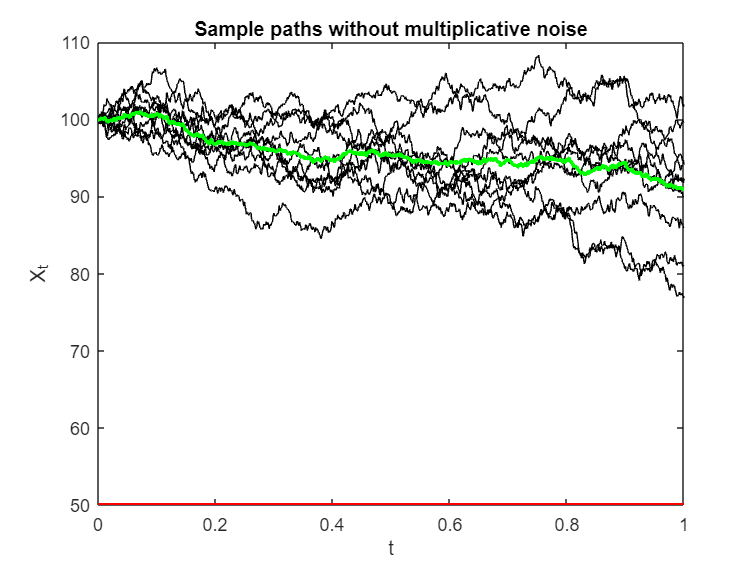

no_noise.plot_trajectory;
title('Sample paths without multiplicative noise');

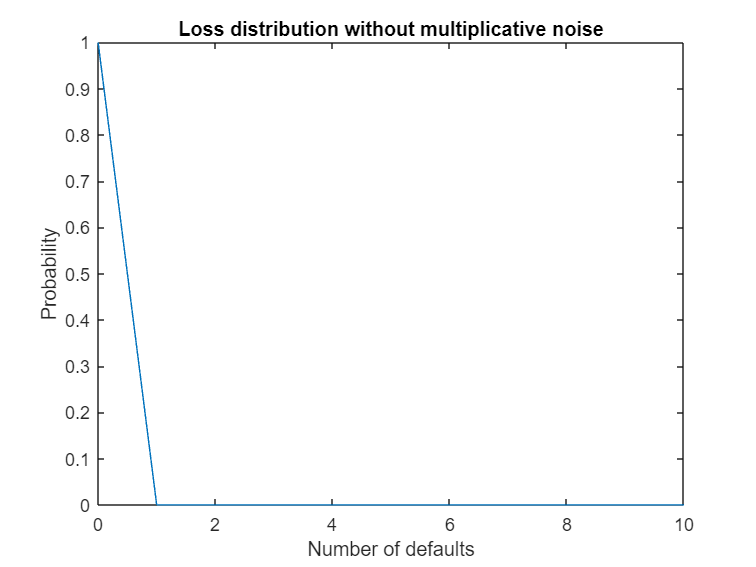

no_noise.plot_loss;
title('Loss distribution without multiplicative noise');

fprintf("Probability of systemic failure: %.2f", no_noise.probfail);

Probability of systemic failure: 0.00

baseline = model(10, ones(10, 1), 10*ones(10, 1));
baseline.g = @(t, x) baseline.sig .* sqrt(x);
baseline.x0 = 100*ones(baseline.N, 1);
baseline.eta = 50;
baseline = baseline.sde_euler;
baseline = baseline.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


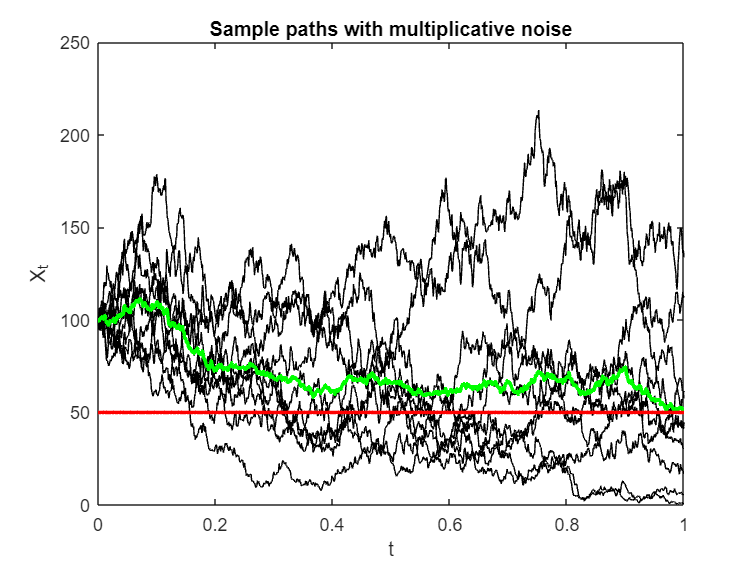

baseline.plot_trajectory;
title('Sample paths with multiplicative noise');

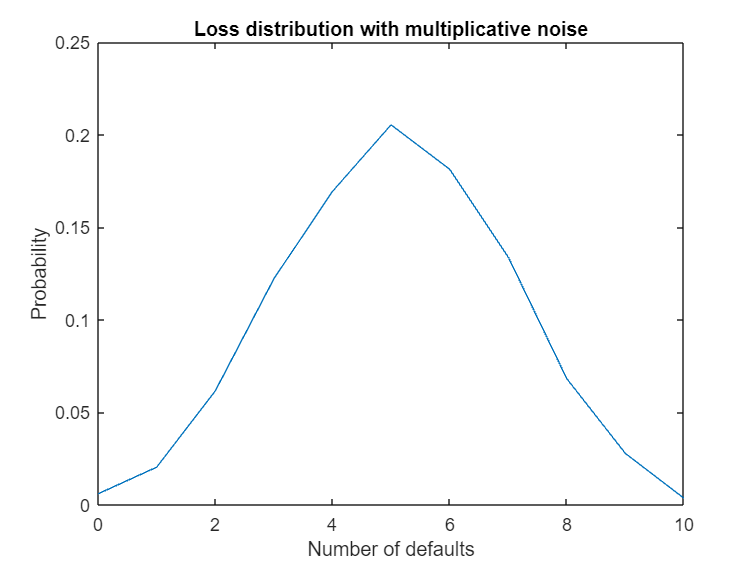

baseline.plot_loss;
title('Loss distribution with multiplicative noise');

fprintf("Probability of systemic failure: %.2f", baseline.probfail);

Probability of systemic failure: 0.01

Multiplicative noise has an asymmetric effect on the mean level of reserves, so while the loss distribution is approximately normal, the probability of the default event is low.

Multiplicative common noise as in Giesecke

dXt = ... + s(rho*Xt dW^{0} + sqrt(1-rho^2) sqrt(Xt) dW^{i})

baseline2 = model(10, ones(10, 1), 10*ones(10, 1));
baseline2.x0 = 100*ones(baseline2.N, 1);
baseline2.eta = 50;
baseline2 = baseline2.multiplicative_common_noise(0.5, 0.5, 0.5);
baseline2 = baseline2.sde_euler;
baseline2 = baseline2.monte_carlo(5000);

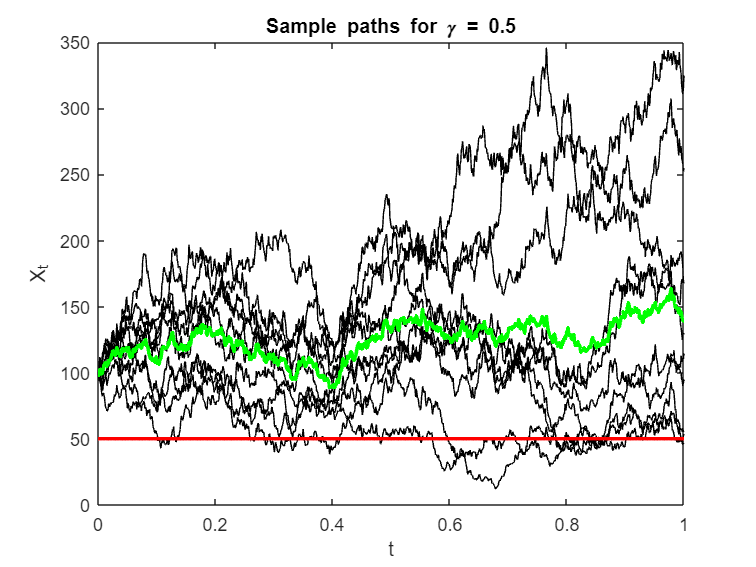

baseline2.plot_trajectory;
title('Sample paths for \gamma = 0.5');

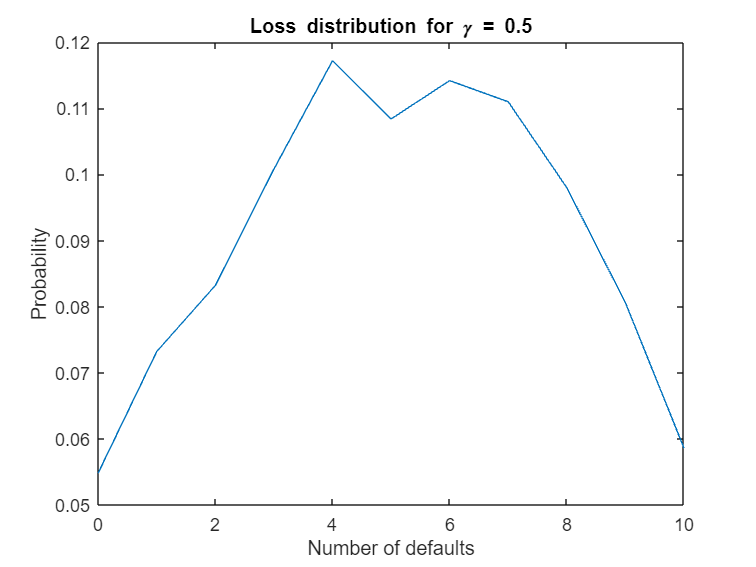

baseline2.plot_loss;
title('Loss distribution for \gamma = 0.5')

fprintf("Probability of systemic failure: %.2f", baseline2.probfail);

Probability of systemic failure: 0.18

baseline3 = model(10, ones(10, 1), 10*ones(10, 1));
baseline3.x0 = 100*ones(baseline3.N, 1);
baseline3.eta = 50;
baseline3 = baseline3.multiplicative_common_noise(0.5, 0.75, 0.5);
baseline3 = baseline3.sde_euler;
baseline3 = baseline3.monte_carlo(5000);

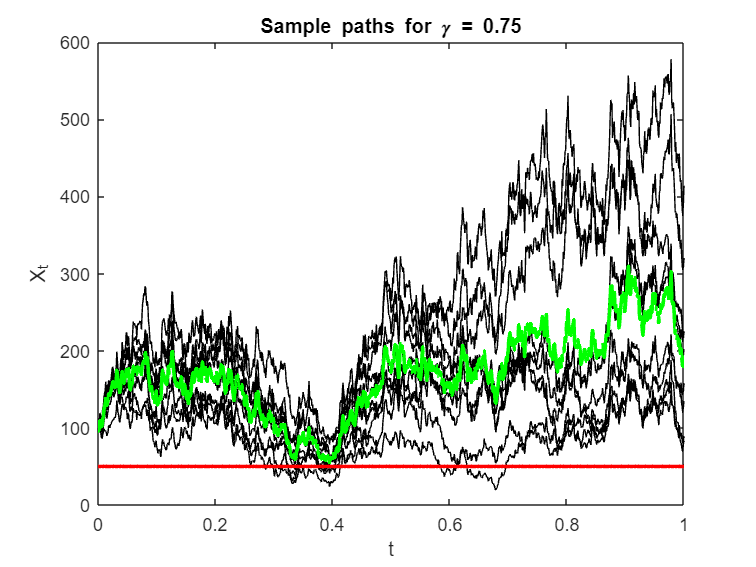

baseline3.plot_trajectory;
title('Sample paths for \gamma = 0.75');

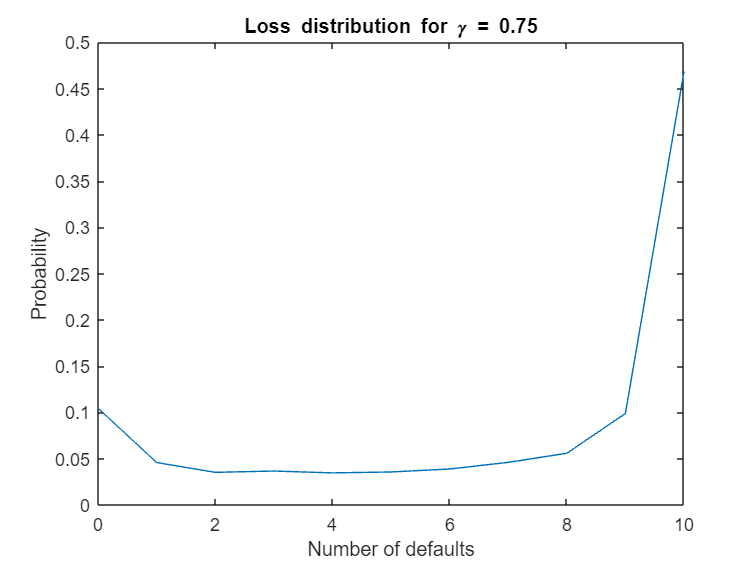

baseline3.plot_loss;
title('Loss distribution for \gamma = 0.75');

fprintf("Probability of systemic failure: %.2f", baseline3.probfail);

Probability of systemic failure: 0.65